addpath('/home/michael/Bambi/thesisMick/bambi-thesis/Matlab/');
A=importdata('/home/michael/CPP.txt');
B=importdata('/home/michael/CPP-SPline.txt');
C=importdata('/home/michael/Border.txt')

C =       691346     5147450
      691357     5147440
      691381     5147430
      691399     5147430
      691417     5147420
      691432     5147420
      691473     5147410
      691501     5147400
      691509     5147390
      691507     5147380


O=importdata('/home/michael/bottomLeftCoord.txt');
W=importdata('/home/michael/WavefrontMatrix.txt');

%W = [W]
W2 = W;

W(W<0)= -3;
W2(W2>=0) = 1

W2 =     -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2    -2     1     1     1     1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2     1     1     1     1     1     1     1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2     1     1     1     1     1     1     1     1     1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2     1     1     1     1     1     1     1     1     1     1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2     1     1     1     1

W2(W2<0) = 0

W2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1


Xo = O(:,1)

Xo = 6.9128e+05

Yo = O(:,2)

Yo = 5.1473e+06

Xc=C(:,1) - Xo

Xc =    62.5948
   73.5948
   97.5948
  115.5948
  133.5948
  148.5948
  189.5948
  217.5948
  225.5948
  223.5948


Yc=C(:,2) - Yo

Yc =   105.8150
   95.8150
   85.8150
   85.8150
   75.8150
   75.8150
   65.8150
   55.8150
   45.8150
   35.8150


%A = A - 1e6
%X=A(:,1) - 6e5 - 8.9e4
%Y=A(:,2) - 5e6 - 1.48e5
X1=A(:,1) - Xo

X1 =    228
   228
   228
   220
   220
   220
   220
   220
   212
   212


Y1=A(:,2) - Yo

Y1 =     28
    36
    44
    52
    44
    36
    28
    20
    12
    20



X2=B(:,1) - Xo

X2 =   227.8262
  227.9783
  228.0000
  228.0000
  227.9987
  227.9893
  227.9640
  227.9147
  227.8333
  227.7120


Y2=B(:,2) - Yo

Y2 =    34.4564
   35.2071
   36.0000
   36.0000
   36.8000
   37.6000
   38.4000
   39.2000
   40.0000
   40.8000


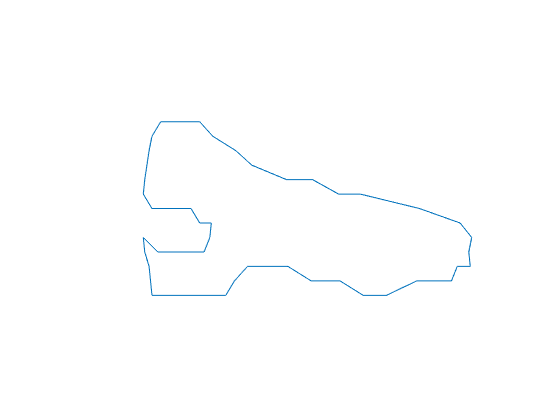




plot(Xc,Yc)
axis image
axis auto
set(gca,'visible','off')

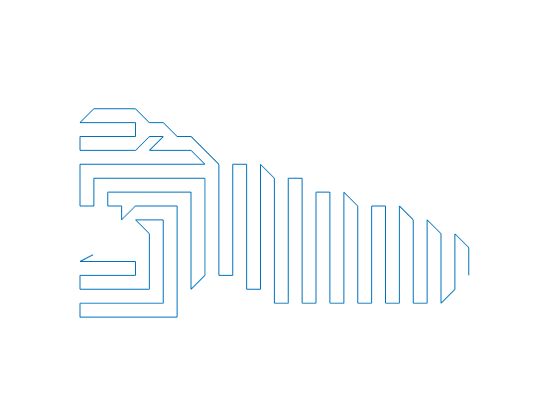

plot(X1,Y1)
axis image
axis auto
set(gca,'visible','off')

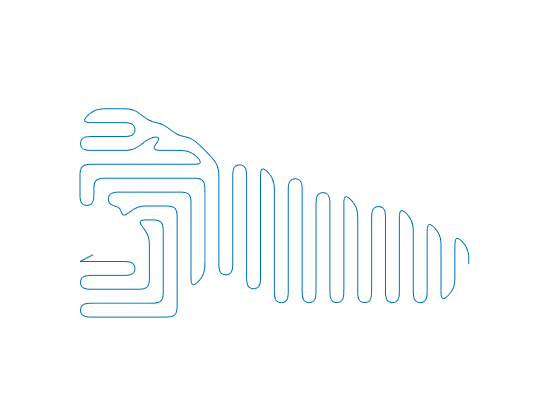

plot(X2,Y2)
axis image
axis auto
set(gca,'visible','off')

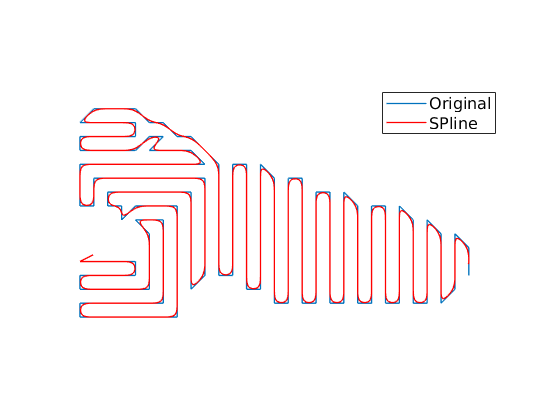

createfigure(X1,Y1,X2,Y2)
axis image
axis auto
set(gca,'visible','off')

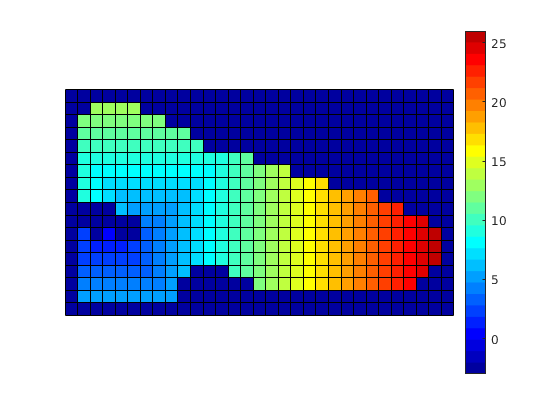

%cmap(1,:) = [255 255 255];
figure
pcolor(W)
set(gca,'Ydir','reverse')
set(gca,'visible','off')
colorbar
axis equal
colormap jet(30)

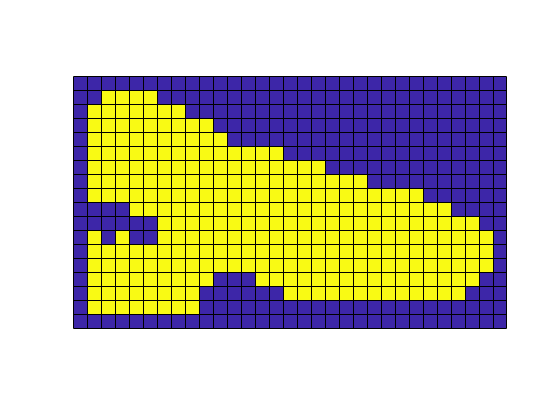


figure
pcolor(W2)
set(gca,'Ydir','reverse')
set(gca,'visible','off')
axis image

%cmap = cmap(fix(([1:20] - (-2))/(20)*64)+1); 
%cmap(5, :) =  [0.8 0.3 0.6]; %some sort of pink
